close all; clear; clc;

# MEGA 2 blade prop, 10-90% ramps

**Record all** points

**file name**: STv2_1_1_MEGA27d2b_20181205_2.mlx

**keywords:** 

**date of test:** date

**file created by:** date, Edmonds

**last updated on:** YYYYMMDD

**primary purpose:** 

**primary input and output variables: **

calculated/not measured from test stand- motor radius and rho. 

measured from test stand- time, ESC us, Torque, Thrust, input voltage, input current, rotational speed (omega), input power, output power, efficiencies (motor, prop, overall), temp probe (by motor)

**functions:** 

**Notes:** 

## Input Variables

Use Atmospheric Condition Calculator to calculate air density

% Air Density
p = 0.002377;                  %SLS [slugs/ft^3]

% Motor Specs
diameter = 27 / 12;
radius = diameter/2;               % [ft]
area = pi * radius^(2);       % [ft^2]

## Measured Data

This format assumes that the data output from RC Benchmark has not been changed

load('STv2_1_1_MEGA27d2b_20181205_2.mat');
time2 = STv2_1_1_MEGA27d2b_20181205_2(:,1);                       % [sec]
PWM2 = STv2_1_1_MEGA27d2b_20181205_2(:,2);                        % [micro sec]
Q2 = STv2_1_1_MEGA27d2b_20181205_2(:,4);                          % [ft.lbf]
T2 = STv2_1_1_MEGA27d2b_20181205_2(:,5);                          % [lbf]
Input_V2 = STv2_1_1_MEGA27d2b_20181205_2(:,6);                    % [Volts]
Input_A2 = STv2_1_1_MEGA27d2b_20181205_2(:,7);                    % [Amps]
rot_speed_rpm2 = STv2_1_1_MEGA27d2b_20181205_2(:,8);              % [RPM]
% convert to RPM for plotting purposes
rot_speed_rad2 = rot_speed_rpm2 .* (pi/30);   % [rad/sec]
P_in_W2 = STv2_1_1_MEGA27d2b_20181205_2(:,9);                     % [Watts]
P_out_W2 = STv2_1_1_MEGA27d2b_20181205_2(:,10);                   % [Watts]
% convert to [ft.lbf/sec]
P_out2 = P_out_W2 .* 0.7478;                  % [ft.lbf/sec]         
P_in2 = P_in_W2 .* 0.7478;                    % [ft.lbf/sec]
Motor_Eff2 = STv2_1_1_MEGA27d2b_20181205_2(:,11);                 % [%]
Prop_Eff2 = STv2_1_1_MEGA27d2b_20181205_2(:,12);                  % [lbf/Watts]
Overall_Eff2 = STv2_1_1_MEGA27d2b_20181205_2(:,13);               % [lbf/Watts]  
ESC_Temp2 = STv2_1_1_MEGA27d2b_20181205_2(:,14);                  % [F]
Motor_Temp2 = STv2_1_1_MEGA27d2b_20181205_2(:,15);                % [F]

disk_loading2 = T2 ./ area;                     % [lb/sq.ft]


Settling_time2 = STv2_1_1_MEGA27d2b_20181205_2(:,17); % [s]
Max_Acc2 = STv2_1_1_MEGA27d2b_20181205_2(:,18);      % [RPM]

throttle2 = (PWM2 - 1000) ./ 10;

## Thrust, Power, and Torque Coefficents

C_T2 = T2 ./ (p .* area * (rot_speed_rad2 * radius).^2);
C_P2 = P_out2 ./ (p .* area .* (rot_speed_rad2 .* radius).^3);
C_Q2 = Q2 ./ (p .* area .* (rot_speed_rad2 .* radius).^(2) .* radius);

## Plots

The following are standard charts. Remove, add, and edit as needed.

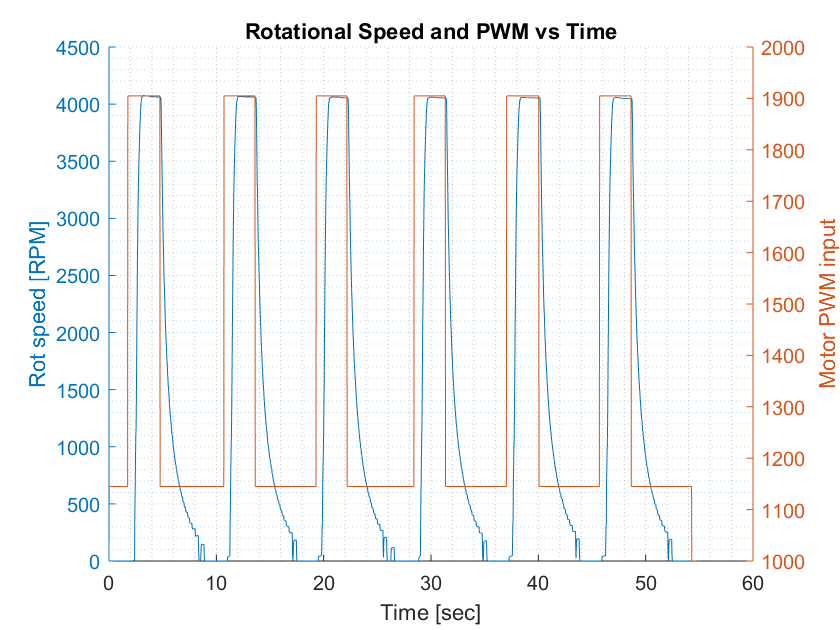



figure(4)
hold on
yyaxis left
plot(time2, rot_speed_rpm2);
ylabel('Rot speed [RPM]');
yyaxis right
plot(time2, PWM2);
ylabel('Motor PWM input');
title('Rotational Speed and PWM vs Time');
xlabel('Time [sec]');
grid('minor');
hold off

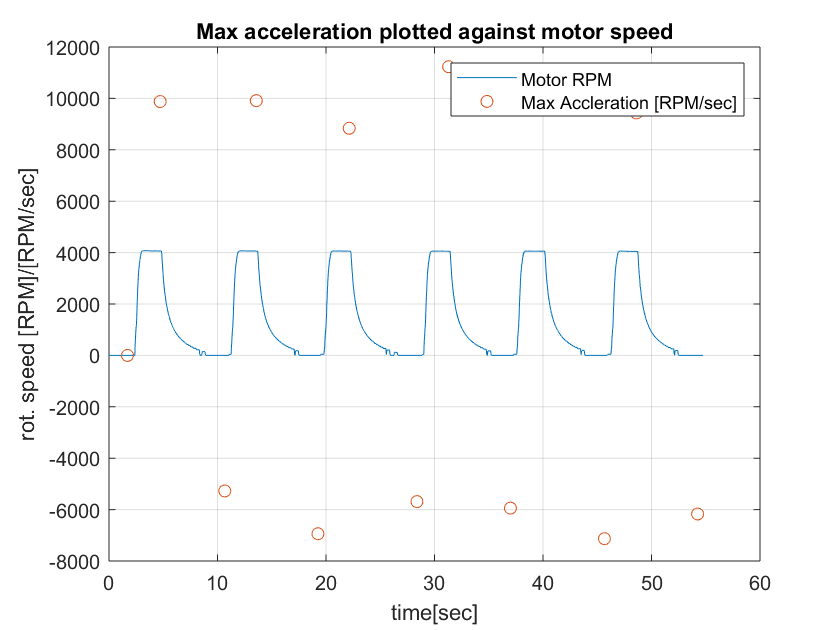



figure(6)
plot(time2, rot_speed_rpm2, time2, Max_Acc2, 'o');
title('Max acceleration plotted against motor speed')
xlabel('time[sec]'); ylabel('rot. speed [RPM]/[RPM/sec]'); 
legend('Motor RPM', 'Max Accleration [RPM/sec]'); grid('on');

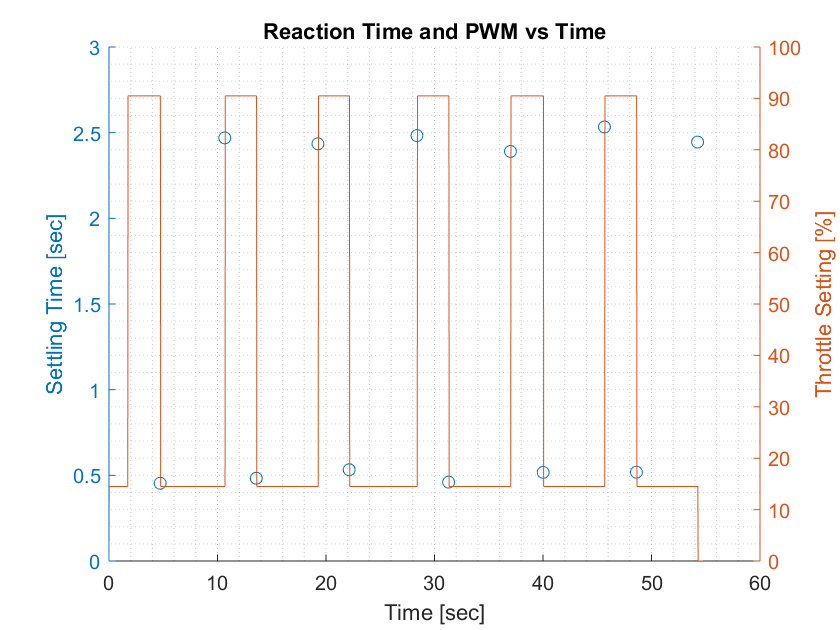


figure(7)
hold on
yyaxis left
plot(time2,Settling_time2, 'o-');
ylabel('Settling Time [sec]');
yyaxis right
plot(time2, throttle2);
ylabel('Throttle Setting [%]');
title('Reaction Time and PWM vs Time');
xlabel('Time [sec]');
grid('minor');
hold off

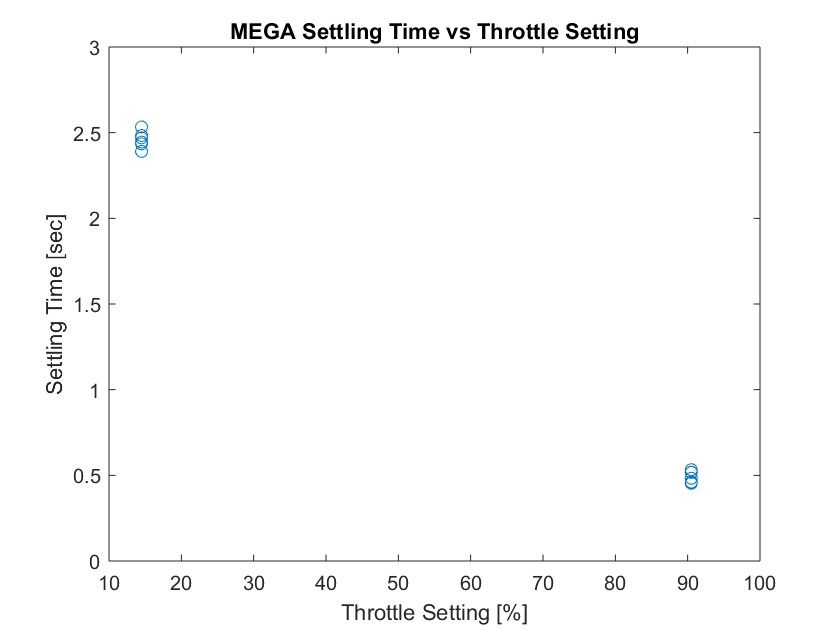


figure(8)
plot(throttle2, Settling_time2, 'o'); title('MEGA Settling Time vs Throttle Setting');
ylabel('Settling Time [sec]'); xlabel('Throttle Setting [%]');